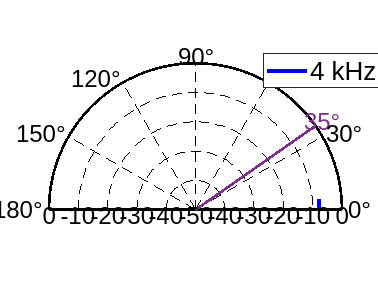

clear 
clc

steerAng = 35;
fs = 41.667e3;
sweepDur = 10;
silenceDur = 2;

f1 = 20;
f2 = 20.8e3;
tone = sweeptone(sweepDur,silenceDur,fs, 'SweepFrequencyRange', [f1 f2])*2;
invTone = flip(tone(1:end-silenceDur*fs))' .* (f2 / f1).^(-(0:(sweepDur*fs-1)) / (sweepDur*fs-1));
tone = [zeros(silenceDur*fs-1,1); tone];
t = 0:1/fs:sweepDur+(silenceDur-1/fs)*2;
tInv = 2:1/fs:(sweepDur+2)-1/fs;

sineTone = sin(2*pi*(0:1/fs:sweepDur)*1000);%.*linspace(0,1,sweepDur*fs+1);
sineTone = [zeros(1,silenceDur*fs-1) sineTone zeros(1,silenceDur*fs-1)];

initialSine = sin(2*pi*(0:1/fs:fs/1000*1/fs)*1000);%*0.5;
tone(round(1*fs):(round(1*fs)+length(initialSine)-1)) = initialSine;
toneNoSilence = tone(2*fs:12*fs-1);

maxDegs = 5;
%outputPower = zeros(maxDegs+1,4096);
%outputFreq = zeros(maxDegs+1,4096);
%outputPower = zeros(maxDegs+1,101);

%f = waitbar(0,'Starting...','Name','Calculating Beampattern');

fftSize = 101*2;
%fftSize = 2^nextpow2(length(convResult));
WaitMessage = parfor_wait(maxDegs, 'Waitbar', true); 
%for d = 0:maxDegs
parfor d = 0:maxDegs    
    
    %fileID = fopen('degree_5');
    fileID = fopen('degree_' + string(d));
    data = fread(fileID,'single'); 
    %data = data/max(data)*2; 
    data = data/(power(2,31)-1);
    numMics = 8;
    numSamples = 190;
    onePacketLength = numSamples*numMics;
    numPacketsInData = floor(length(data)/onePacketLength);
    beamformData = zeros(numSamples,1);
    for i = 1:numPacketsInData
        beamformData = [beamformData; data((1+numSamples*7*i):numSamples*7*i+numSamples)];
    end
    beamformData = beamformData(numSamples+1:end,:)';
    
    %beamformData = beamformData/max(abs(beamformData));
    % forsøg ud fra impulse
    %impulse = impzest(tone, beamformData');
    %impulse = impulse / max(abs(impulse));
    % outputPower(d+1,:) = fft(impulse,101);

    % mangler at gange invers exp filter på med dette approach
    %outputPower(d+1,:) = fft(beamformData,101);
    %xcorr i første 0.5:1.5 sekund
    %shift
    %conv
    %fft

    %stft(impulse,fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=4096)
    %[outputPower(d+1,:), outputFreq(d+1,:)] = pspectrum(impulse,fs);

    [c, lags] = xcorr(tone(round(0.5*fs):round(1.5*fs)),beamformData(round(0.5*fs):round(1.5*fs)),'normalized');
    [~, I] = max(abs(c));
    %[maxVal, I] = max(abs(c));
    lagDiff = lags(I);
    % Shift beamformData such the syncTone is at 1s
    if lagDiff > 0
        bfDataShifted = [zeros(1, lagDiff), beamformData(1:end-lagDiff)];
    elseif lagDiff < 0
        bfDataShifted = [beamformData(-lagDiff+1:end), zeros(1, -lagDiff)];
    else
        bfDataShifted = beamformData;
    end
    %disp(lagDiff)
    %disp(maxVal)

    
    bfDataShifted = bfDataShifted(2*fs:12*fs); % Shift to start of sweep (2s)
    %bfDataShifted = bfDataShifted/max(bfDataShifted); % Normalize

    % Convolve measured data with inverse tone
    convResult = conv(bfDataShifted, invTone);
    %convResult = conv(toneNoSilence, invTone);
    %convResult = toneNoSilence;
    %plot(convResult)
    
    
    % Compute FFT
    % N = length(convResult);
    % fftResult = fft(convResult);%, fftSize);
    % %fftResult = fft(bfDataShifted, fftSize);
    % fftResult = fftResult(1:(round(N/2)+1));
    % psdResult = (1/(fs*N)) * abs(fftResult).^2;
    % psdResult(2:end-1) = 2*psdResult(2:end-1);

    [outputPower(d+1,:), outputFreq(d+1,:)] = periodogram(convResult,[],fftSize)

    %pspectrum(convResult,fs)

    %outputPower(d+1,:) = psdResult;

    %[outputPower(d+1,:), outputFreq(d+1,:)] = pspectrum(conv(bfDataShifted,invTone),fs)
    %[outputPower(d+1,:), outputFreq(d+1,:)] = pspectrum(conv(beamformData(2*fs:12*fs),invTone),fs)
    %pspectrum(conv(bfDataShifted,invTone),fs)
    
    %fftResult = fft(beamformData, fftSize*2);
    %fftResult = fft(conv(bfDataShifted, invTone),fftSize*2); %fft returns

    %fftResult = fft(bfDataShifted,fftSize*2);
    %fftResult = fft(beamformData, fftSize*2);
    

    %negative frequencies also
    %outputPower(d+1,:) = fftResult(1:end/2);

    %pspectrum(bfDataShifted,fs)
    %pspectrum(conv(bfDataShifted,invTone),fs)

    WaitMessage.Send; 
end
%delete(f)
WaitMessage.Destroy
outputdB = pow2db(outputPower); %FFT
%outputdB = pow2db(outputPower);
%outputdB = outputdB - max(outputdB);

%outputdB = movmean(outputdB,5);

%outputFreq = linspace(0,41667/2,fftSize); % Use this for when using fft
%and not pspectrum
%fftFrequencies = 0:fs/fftSize:fs/2;
%fftFrequencies = linspace(0,fs/2,length(outputdB));*fs/(2*pi)
%plot(fftFrequencies, outputdB(maxDegs,:));
outputFreq = outputFreq*fs/(2*pi);
%outputFreq = fftFrequencies;
%plot(outputFreq(1,:), outputdB(maxDegs,:))
circPlot(outputFreq(1,20), (0:maxDegs)*pi/180, outputdB(maxDegs,20)', steerAng)

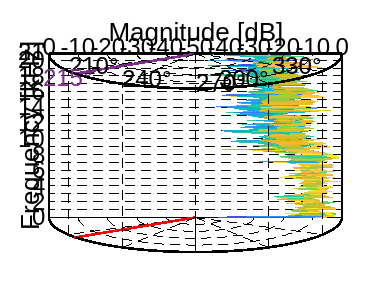

cylindricalPlot(outputFreq(1,:), (0:maxDegs)*pi/180, movmean(outputdB',1), 180-steerAng, [180, 10])